# Create and Customize Histograms

Histograms are a type of bar plot for numeric data that group the data into bins. 

### Read Cars Data

We will use "`carbig.mat" `to demonstrate how to create and customize histograms. The MAT-file contains various measurement data of 406 models of cars such as MPG, Horsepower, Displacement, etc. released in different countries between 1970 and 1982. 

load("carbig.mat")

### Basic Histogram

View the miles per gallon (MPG) distribution for the 406 cars and observe how the distribution changes with the number of bins chosen. When the number of bins is not specified, an automatic binning algorithm returns bins with a uniform width.

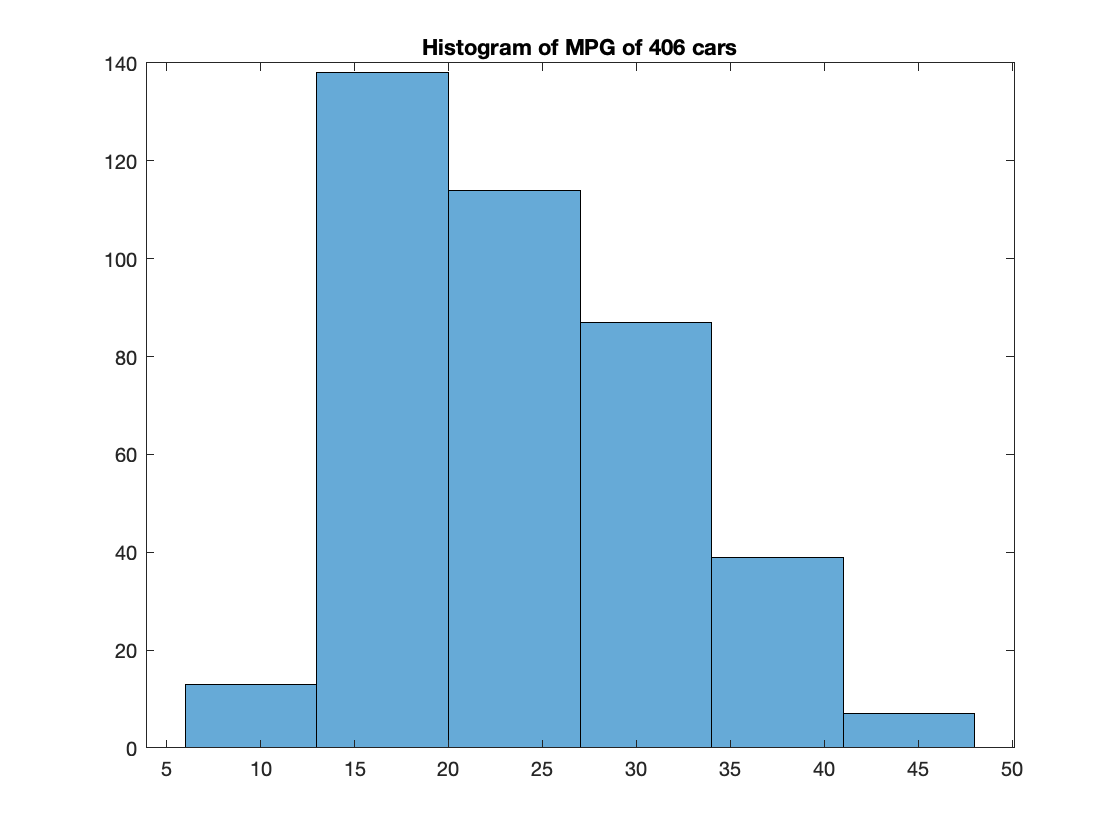

numberOfBins = 6;
histogram(MPG, numberOfBins);
title("Histogram of MPG of 406 cars");

## Customization

### Display Normalized Data on Y-Axis

Instead of using the count on the y-axis, you can also view the proportion of each bin of the overall set on the y-axis using the *Normalization* property as a Name, Value pair argument to `histogram`.

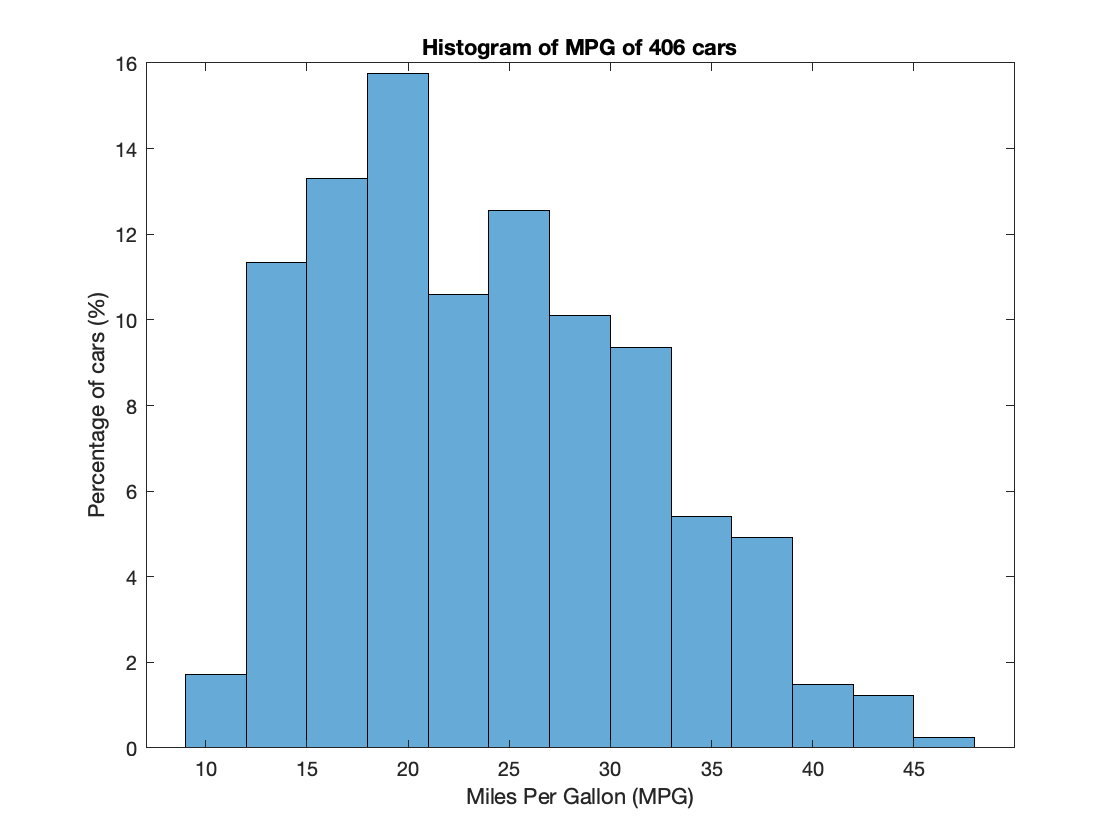

h = histogram(MPG,...    
   "Normalization","probability");      % Specify "probability" in the Normalization field 
title("Histogram of MPG of 406 cars")
xlabel("Miles Per Gallon (MPG)")
ylabel("Percentage of cars (%)")
yticklabels(yticks*100);                % Set the y-axis label values to represent percentages

### Specify Bin Boundaries, Bar Color and Transparency

If specific bin boundaries are desired such as 5 MPG intervals starting at 5 MPG, specify the bin *edges* as the second argument to `histogram`. You can also change the color and transparency of the histogram bars using *FaceColor* and *FaceAlpha* Name, Value pair arguments. Add axes labels and a title to complete the plot.

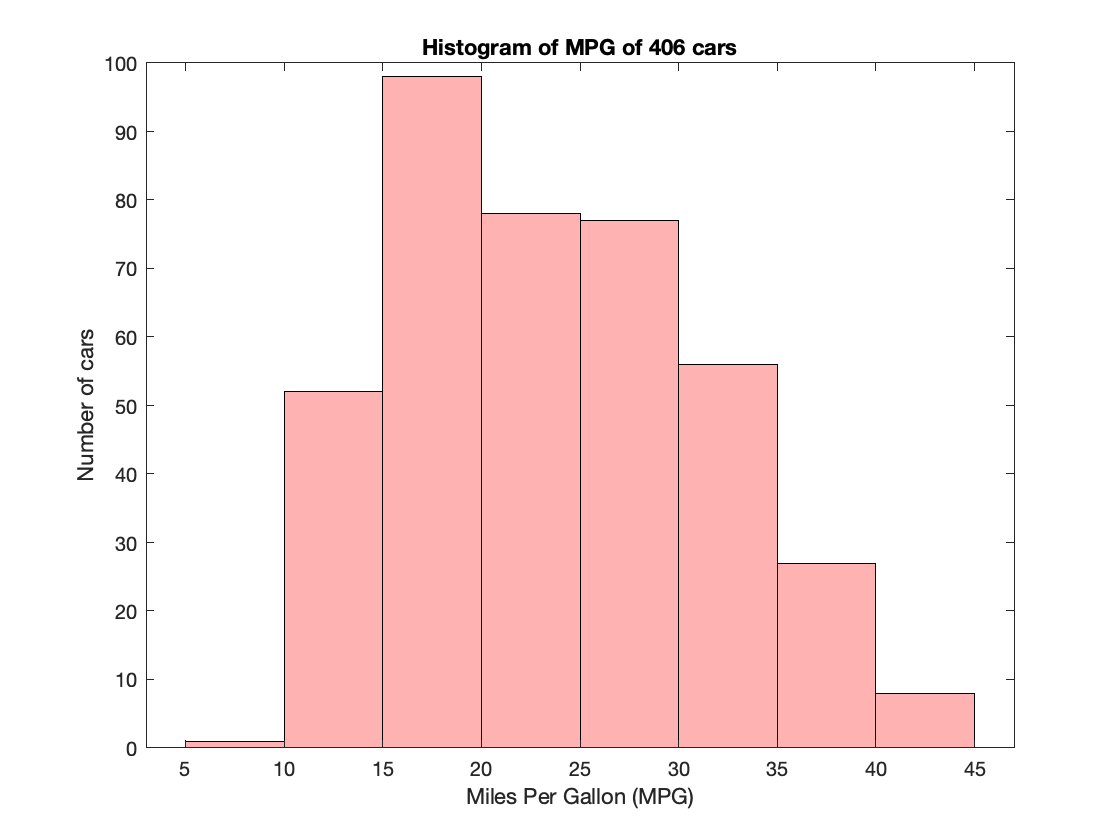

barColor = "red";
barTransparency = 0.3;

edges = 5:5:45;                  % Create vector of desired edges
figure
h1 = histogram(MPG, edges,...    % Use edges as the second argument
   "FaceColor",barColor,...      % Specify bar color
   "FaceAlpha",barTransparency); % Specify bar transparency between 0 and 1

title("Histogram of MPG of 406 cars")
xlabel("Miles Per Gallon (MPG)")
ylabel("Number of cars")

## **Additional Information**

### **Get All Histogram Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Histogram, uncomment the following code. View or modify these properties using dot notation.

% get(h)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[histogram](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

Copyright (c) 2021, The MathWorks, Inc.